# 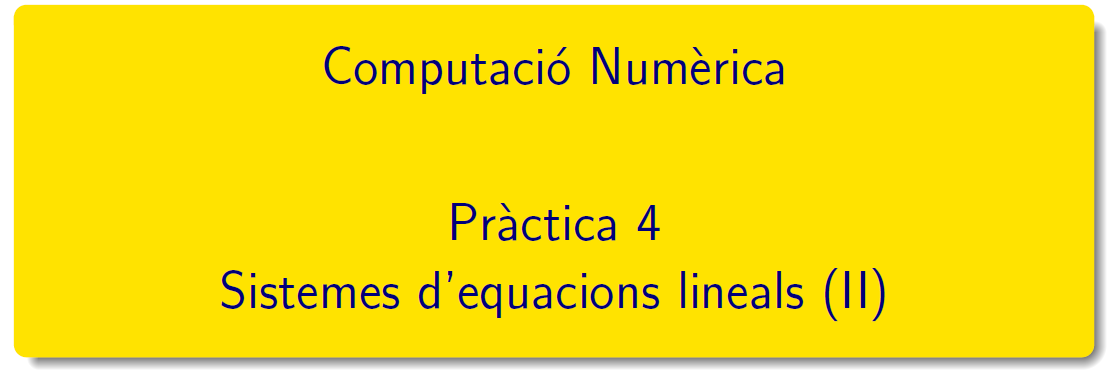

=============================================================================

# Pràctica 4 - Mètodes iteratius

`Document preparat per M. Àngela Grau Gotés, 8 de març de 2023`

## Introducció

A més a més dels exercicis d'aquest script teniu disponibles exercicis  en el document CN_full2.pdf, el podeu trobar en el campus virtual. 

**Radi espectral **

Definició i propietats en el document bloc 0 (pàg 16). Càlcul de valors i vectors propis en Matlab®: consulteu [eigs ](https://www.mathworks.com/help/matlab/ref/eigs.html)i [eig](https://es.mathworks.com/help/matlab/ref/eig.html) 

H = hilb(4)

H =     1.0000    0.5000    0.3333    0.2500
    0.5000    0.3333    0.2500    0.2000
    0.3333    0.2500    0.2000    0.1667
    0.2500    0.2000    0.1667    0.1429


vaps = eig(H), rho = abs(eigs(H,1))  % radi = vap de mòdul màxim

vaps =     0.0001
    0.0067
    0.1691
    1.5002


rho = 1.5002

## Mètodes iteratius estacionaris 

Són els mètodes de Jacobi, de Gauss-Seidel i de sobrerelaxació (SOR)


$$Ax=b \Longleftrightarrow x^{k+1}=B\,x^{k}+c\,,\quad \forall\ k\ge0\,.$$


### Submatrius D, L i U de la matriu A

 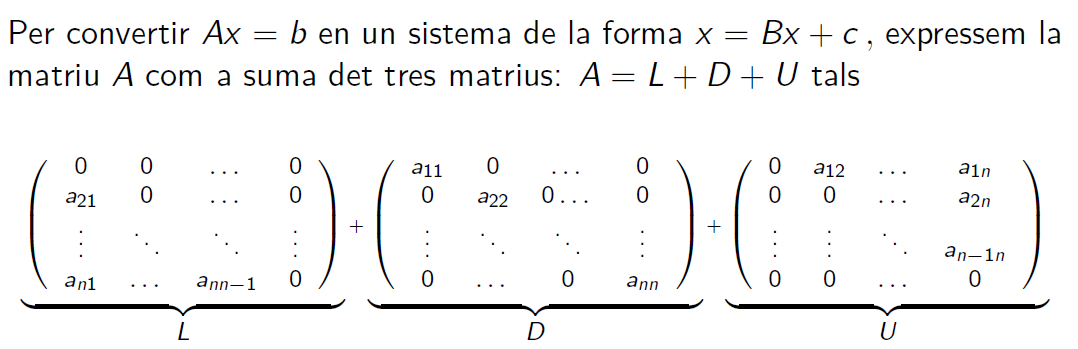     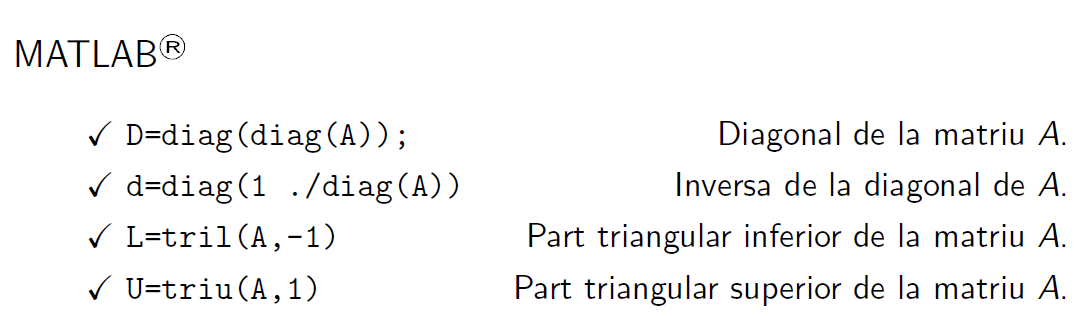

`Exercici 1.`` Obteniu les submatrius L, D, U per a la matriu `$A=\left( \begin{array}{rrr}
1 & 0 & 1 \\
-1 & 1 & 0\\
1 & 2 & -3
\end{array} \right)$

A = [1 0 1; -1 1 0; 1 2 -3]; b=[4;1;-4];

### **Practiquem: Mètodes de Jacobi i de Gauss-Seidel**

`Exercici 2.` `Determineu  les matrius d'iteració del mètode de Jacobi i del mètode de Gauss-Seidel del sistema Ax=b donat per `


$$A=\left( \begin{array}{rrr}
1 & 0 & 1 \\
-1 & 1 & 0\\
1 & 2 & -3
\end{array} \right)\quad\quad
b=\left(\begin{array}{r}   4\\ 1\\-4\end{array} \right) 
\quad \Longrightarrow \quad
x=\left(\begin{array}{r}   1\\ 2\\3\end{array} \right) $$


Matrius de Jacobi:  $ x_{Ji}^{(k+1)} = x_i^{(k)} + \displaystyle\frac{1}{a_{ii}}\left( {b_i-\displaystyle \sum_{j=1}^{n}a_{ij}x_j^{(k)}}\right),\quad   k\ge0\,$

Matrius de Gauss-Seidel:  $x_{Si}^{(k+1)} = x_i^{(k)} +\displaystyle \frac{1}{a_{ii}}\left( {b_i-\displaystyle \sum_{j=1}^{i-1}a_{ij}x_j^{(k+1)} -\sum_{j=i+1}^{n}a_{ij}x_j^{(k)}}\right),\quad   k\ge0$

% Dades del problema
A = [1 0 1; -1 1 0; 1 2 -3];
b = [4 1 4];
x = [1 2 3];

% Descomposición de la matriz A en D, L, U
D = diag(diag(A));
L = tril(A, -1);
U = triu(A, 1);

% Matriz de iteración para el método de Jacobi
G_Jacobi = -inv(D) * (L + U);

% Matriz de iteración para el método de Gauss-Seidel
G_GS = -inv(D + L) * U;

% Mostrar matrices de iteración
disp('Matriz de iteración de Jacobi:');

Matriz de iteración de Jacobi:


disp(G_Jacobi);

         0         0   -1.0000
    1.0000         0         0
    0.3333    0.6667         0




disp('Matriz de iteración de Gauss-Seidel:');

Matriz de iteración de Gauss-Seidel:


disp(G_GS);

     0     0    -1
     0     0    -1
     0     0    -1



### **Practiquem: Mètodes de SOR_Jacobi i de SOR_Gauss-Seidel**

`Exercici 3.` `Determineu  les matrius d'iteració del mètode de SOR_Jacobi i del mètode de SOR_Gauss-Seidel del sistema Ax=b donat per `


$$A=\left( \begin{array}{rrr}
1 & 0 & 1 \\
-1 & 1 & 0\\
1 & 2 & -3
\end{array} \right)\quad\quad
b=\left(\begin{array}{r}   4\\ 1\\-4\end{array} \right) 
\quad \Longrightarrow \quad
x=\left(\begin{array}{r}   1\\ 2\\3\end{array} \right) $$


Matrius de SOR-Jacobi:  $ x_{Ji}^{(k+1)} = x_i^{(k)} + \displaystyle\frac{\omega}{a_{ii}}\left( {b_i-\displaystyle \sum_{j=1}^{n}a_{ij}x_j^{(k)}}\right),\quad   k\ge0\,$ i per $\omega$ donat, tal que $0<\omega<2$

Matrius de SOR-Gauss-Seidel: $x_{Si}^{(k+1)} = x_i^{(k)} +\displaystyle \frac{\omega}{a_{ii}}\left( {b_i-\displaystyle \sum_{j=1}^{i-1}a_{ij}x_j^{(k+1)} -\sum_{j=i}^{n}a_{ij}x_j^{(k)}}\right),\quad   k\ge0$  i per $\omega$ donat, tal que $0<\omega<2$

% Valor de relaxació omega (ω)
omega = 1.5; % Pots canviar aquest valor segons sigui necessari

% Matriu d'iteració SOR-Jacobi
M_sor_jacobi = inv(D + omega * L) * ((1 - omega) * D - omega * U);

% Matriu d'iteració SOR-Gauss-Seidel
M_sor_gs = inv(D + omega * L) * ((1 - omega) * D - omega * U);

% Mostrar les matrius d'iteració
disp('Matriu d''iteració SOR-Jacobi:')

Matriu d'iteració SOR-Jacobi:


disp(M_sor_jacobi)

   -0.5000         0   -1.5000
   -0.7500   -0.5000   -2.2500
   -1.0000   -0.5000   -3.5000




disp('Matriu d''iteració SOR-Gauss-Seidel:')

Matriu d'iteració SOR-Gauss-Seidel:


disp(M_sor_gs)

   -0.5000         0   -1.5000
   -0.7500   -0.5000   -2.2500
   -1.0000   -0.5000   -3.5000



### Teorema de convergència.

Un esquema iteratiu $x^{k+1}=B\,x^{k}+c\,,\quad \forall\ k\ge0\,$ per a resoldre $Ax=b$ convergeix ssi $\rho(B)<1\,.$

`Exercici 4.`` Verifiqueu el teorema de convergència ``"a priori" ``per als mètodes de Jacobi i Gauss-Seidel`

A = [1 0 1; -1 1 0; 1 2 -3];
D = diag(diag(A));
L = tril(A, -1);
U = triu(A, 1);

M_jacobi = -inv(D) * (L + U);
radio_espectral_jacobi = max(abs(eig(M_jacobi)));

if radio_espectral_jacobi < 1
    fprintf('El mètode de Jacobi convergeix perquè el radi espectral és menor que 1.\n');
else
    fprintf('El mètode de Jacobi no convergeix perquè el radi espectral no és menor que 1.\n');
end

El mètode de Jacobi convergeix perquè el radi espectral és menor que 1.



M_gs = -inv(D + L) * U;
radio_espectral_gs = max(abs(eig(M_gs)));

if radio_espectral_gs < 1
    fprintf('El mètode de Gauss-Seidel convergeix perquè el radi espectral és menor que 1.\n');
else
    fprintf('El mètode de Gauss-Seidel no convergeix perquè el radi espectral no és menor que 1.\n');
end

El mètode de Gauss-Seidel no convergeix perquè el radi espectral no és menor que 1.


`Exercici 5. ``Verifiqueu el teorema de convergència ``"a priori" ``per als mètodes SOR per `$0<\omega<2$

omega = linspace(0.1, 1.9, 19); % Valores de omega entre 0 y 2 (excluidos)

for w = omega
    M_sor = inv(D + w * L) * ((1 - w) * D - w * U);
    radio_espectral_sor = max(abs(eig(M_sor)));

    if radio_espectral_sor < 1
        fprintf('El mètode SOR amb omega=%.1f convergeix perquè el radi espectral és menor que 1.\n', w);
    else
        fprintf('El mètode SOR amb omega=%.1f no convergeix perquè el radi espectral no és menor que 1.\n', w);
    end
end

El mètode SOR amb omega=0.1 convergeix perquè el radi espectral és menor que 1.
El mètode SOR amb omega=0.2 convergeix perquè el radi espectral és menor que 1.
El mètode SOR amb omega=0.3 convergeix perquè el radi espectral és menor que 1.
El mètode SOR amb omega=0.4 convergeix perquè el radi espectral és menor que 1.
El mètode SOR amb omega=0.5 convergeix perquè el radi espectral és menor que 1.
El mètode SOR amb omega=0.6 convergeix perquè el radi espectral és menor que 1.
El mètode SOR amb omega=0.7 convergeix perquè el radi espectral és menor que 1.
El mètode SOR amb omega=0.8 convergeix perquè el radi espectral és menor que 1.
El mètode SOR amb omega=0.9 convergeix perquè el radi espectral és menor que 1.
El mètode SOR amb omega=1.0 convergeix perquè el radi espectral és menor que 1.


El mètode SOR amb omega=1.1 no convergeix perquè el radi espectral no és menor que 1.
El mètode SOR amb omega=1.2 no convergeix perquè el radi espectral no és menor que 1.
El mètode SOR amb omega=1.3 no convergeix perquè el radi espectral no és menor que 1.
El mètode SOR amb omega=1.4 no convergeix perquè el radi espectral no és menor que 1.
El mètode SOR amb omega=1.5 no convergeix perquè el radi espectral no és menor que 1.
El mètode SOR amb omega=1.6 no convergeix perquè el radi espectral no és menor que 1.
El mètode SOR amb omega=1.7 no convergeix perquè el radi espectral no és menor que 1.
El mètode SOR amb omega=1.8 no convergeix perquè el radi espectral no és menor que 1.
El mètode SOR amb omega=1.9 no convergeix perquè el radi espectral no és menor que 1.


#### Exercici 1

Es l'exercici 15 - llista de problemes del tema 2

Escriviu un programa que implementi els algoritmes de Jacobi, Gauss - Seidel i els mètodes SOR amb paràmetre $\omega$. 

- En una primera aproximació determineu les 10 primeres iteracions dels  mètodes i estudieu el vector residu per cada mètode. 

- Introduiu un test de convergència per als algoritmes de Jacobi, de Gauss - Seidel i SOR. 

- Proveu-lo per:


$$$$A=\left( \begin{array}{rrrr}
10 & -1 & 2 & 0 \\
-1 & 11 & -1 & 3\\
2 & -1 & 10 & -1\\
0 & 3 & -1 & 8
\end{array} \right)\quad\quad
b=\left(\begin{array}{r}   6\\ 25\\-11\\ 15\end{array} \right)
\qquad
x=\left(\begin{array}{r}   1\\ 2\\-1\\ 1\end{array} \right)$$
$$


clearvars
A = [10 -1 2  0; -1 11 -1 3; 2 -1 10 -1; 0 3 -1 8], b=[6;25;-11;15];

A =     10    -1     2     0
    -1    11    -1     3
     2    -1    10    -1
     0     3    -1     8


Mètode de Jacobi

Mètode de Gauss-Seidel

Mètode de SOR-Jacobi

Mètode de SOR - Gauss-Seidel

### **Test de parada **

Fixada una tolerància $\epsilon$ l'algoritme s'ha de parar en la iteració $k$ tal que $||e^{(k)}||=||x-x^{(k)}||<\epsilon$

Com que no coneixem $x$, treballem amb el vector residu: $r^{(k)}=b-Ax^{(k)}$ i apliquem el resultat $\displaystyle\frac{||r^{(k)}||}{||b||}<\epsilon
\Longrightarrow
\frac{||e^{(k)}||}{||x||}<\epsilon\,cond(A)$

#### Exercici 2

Joc de proves de l'exercici 15 - llista de problemes del tema 2

Introduiu un test de convergència per als algoritmes de Jacobi, de Gauss - Seidel i SOR. Proveu-lo per

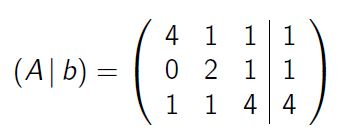     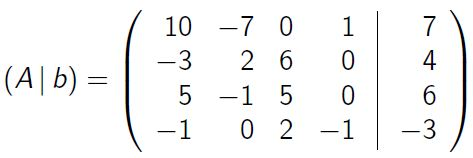      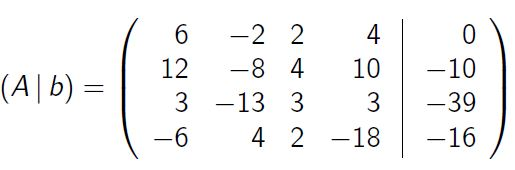

A = [4 1 1; 0 2 1; 1 1 4], b = [1;1;4]; 
% Jacobi
A = [4 1 1; 0 2 1; 1 1 4];
b = [1; 1; 4];
tolerancia = 1e-6;
max_iter = 1000;

n = size(A, 1);
x = zeros(n, 1);
x_nuevo = zeros(n, 1);

for k = 1:max_iter
    for i = 1:n
        x_nuevo(i) = (1/A(i,i))*(b(i) - A(i, [1:i-1, i+1:n]) * x([1:i-1, i+1:n]));
    end
    
    residuo = norm(b - A * x_nuevo) / norm(b);

A =      4     1     1
     0     2     1
     1     1     4


    if residuo < tolerancia * cond(A)
        break;
    end
    
    x = x_nuevo;
end
x_jacobi = x_nuevo;

%GS

x = zeros(n, 1);

for k = 1:max_iter
    for i = 1:n
        x(i) = (1/A(i,i))*(b(i) - A(i, [1:i-1, i+1:n]) * x([1:i-1, i+1:n]));
    end
    
    residuo = norm(b - A * x) / norm(b);
    if residuo < tolerancia * cond(A)
        break;
    end
end
x_gs = x;

%SOR:
omega = 1.5;
x = zeros(n, 1);

for k = 1:max_iter
    for i = 1:n
        x_gs = (1/A(i,i))*(b(i) - A(i, [1:i-1, i+1:n]) * x([1:i-1, i+1:n]));
        x(i) = omega * x_gs + (1 - omega) * x(i);
    end
    
    residuo = norm(b - A * x) / norm(b);
    if residuo < tolerancia * cond(A)
        break;
    end
end
x_sor = x;

A = [10 -7 0 1;-3 2 6 0; 5 -1 5 0; -1 0 2 -1], b = [7;4;6;-3]; 
% Per fer...

A = [6 -2 2 4; 12 -8 4 10; 3 -13 3 3; -6 4 2 -18], b = [0; -10; -39; -16]; 
% Per fer...


### Practiquem ...

#### Exercici 3

Es l'exercici 16 - llista de problemes del tema 2

Resoleu pel mètode de Jacobi i de Gauss-Seidel el sistema $Ax=b$ donat per


$$A=\left( \begin{array}{rrrr}
	10 & -1 & 2 & 0 \\
	-1 & 11 & -1 & 3\\
	2 & -1 & 10 & -1\\
	0 & 3 & -1 & 8
	\end{array} \right)\quad\quad
	b=\left(\begin{array}{r}   6\\ 25\\-11\\ 15\end{array} \right)$$


prenent $x^{(0)}=(0\,,0\,,0\,,0)^{\top}$ i una tolerància $\epsilon = 0.5\cdot 10^{-12}$. Quantes iteracions calen?

Calculeu els errors $\delta^k = ||x^k-x^{k-1}||$ i estudieu $\delta^k/\delta^{k-1}\,.$

% Datos
A = [10 -1 2  0; -1  11 -1 3; 2 -1 10 -1; 0 3 -1 8];
b = [6; 25; -11; 15];
tolerancia = 0.5 * 1e-12;

A =     10    -7     0     1
    -3     2     6     0
     5    -1     5     0
    -1     0     2    -1


x0 = zeros(4, 1);

% Método de Jacobi

A =      6    -2     2     4
    12    -8     4    10
     3   -13     3     3
    -6     4     2   -18


n = size(A, 1);
x = x0;
x_nuevo = zeros(n, 1);
iteraciones_jacobi = 0;
delta_rel = [];

for k = 1:1000
    for i = 1:n
        x_nuevo(i) = (1/A(i,i))*(b(i) - A(i, [1:i-1, i+1:n]) * x([1:i-1, i+1:n]));
    end
    
    delta = norm(x_nuevo - x);
    delta_rel = [delta_rel, delta];
    
    if delta < tolerancia
        break;
    end
    
    x = x_nuevo;
    iteraciones_jacobi = iteraciones_jacobi + 1;
end

x_jacobi = x_nuevo;

% Estudio de errores y ratios
relacion_jacobi = delta_rel(2:end) ./ delta_rel(1:end-1);

% Presentación de resultados
disp('Mètode de Jacobi')
disp(['El mètode és convergent, la solució per rho =  0.426,  tol = 4.46e-13,  k=' num2str(iteraciones_jacobi) '  és'])
disp(x_jacobi)

% Gráficas
figure
plot(0:iteraciones_jacobi, delta_rel, 'bd')
xlabel('k')
ylabel('||x^k - x^{k-1}||')
title('Estudi errors - Jacobi')

figure
plot(1:iteraciones_jacobi, relacion_jacobi, 'rx')
hold on
plot([2, iteraciones_jacobi], [0.426, 0.426], 'k--')
xlabel('k')
ylabel('\Delta^k / \Delta^{k-1}')
title('Estudi ratios - Jacobi')
legend('\Delta^k / \Delta^{k-1}', '\rho')

Mètode de Jacobi


El mètode és convergent, la solució per rho =  0.426,  tol = 4.46e-13,  k=35  és


    1.0000
    2.0000
   -1.0000
    1.0000



#### Exercici 4

Determineu el factor $\omega$ per a resoldre


$$\left\{ \begin{array}{rcrcrcrcr}
		10x & + & 5y &  &   &   &    & = & 6\\ %[-0.3em]
		5x & + & 10y &- & 4z &   &   & = & 25\\ %[-0.3em]
	 	   & - & 4y & + & 8z  & - & t  & = & -11\\ %[-0.3em]
		   &  &   & - & z & + & 5t  & = & -11
	\end{array}\right.$$


fent ús dels mètodes de sobrerelaxació variants de Jacobi i de Gauss-Seidel. 

Feu un estudi per $0<\omega<2$. Presenteu els resultats en una taula.

% Per fer ... resultats -> exercici4_prac03.html
A = [10 5 0 0; 5 10 -4 0; 0 -4 8 -1; 0 0 -1 5];
b = [6; 25; -11; -11]; 

#### Exercici 5

Resoleu pels mètodes de classe el sistema $Ax=b$ donat per 


$$A=\left( \begin{array}{rrrr}
		15 & -5 &  0 & -5\\
		-5 & 12 & -2 &  0\\
		0 & -2 &  6 & -2\\
		-5 &  0 & -2 &  9
	\end{array} \right)\quad
	b=\left(\begin{array}{r}   -3.45\\ 9.96\\0\\ 0\end{array} \right)\quad
	x^{*}=\left(\begin{array}{c}   0.14\\ 0.95\\0.37\\ 0.16\end{array} \right)$$


prenent $x^{(0)}=(0\,,0\,,0\,,0)^{\top}$ i una tolerància Quantes iteracions calen?

Calculeu els errors $e^k = ||x^k-x^{\ast}||$,   $\delta^k = ||x^k-x^{k-1}||$ i estudieu $e^k/e^{k-1}\,,\quad$  $\delta^k/\delta^{k-1}\,.$ 

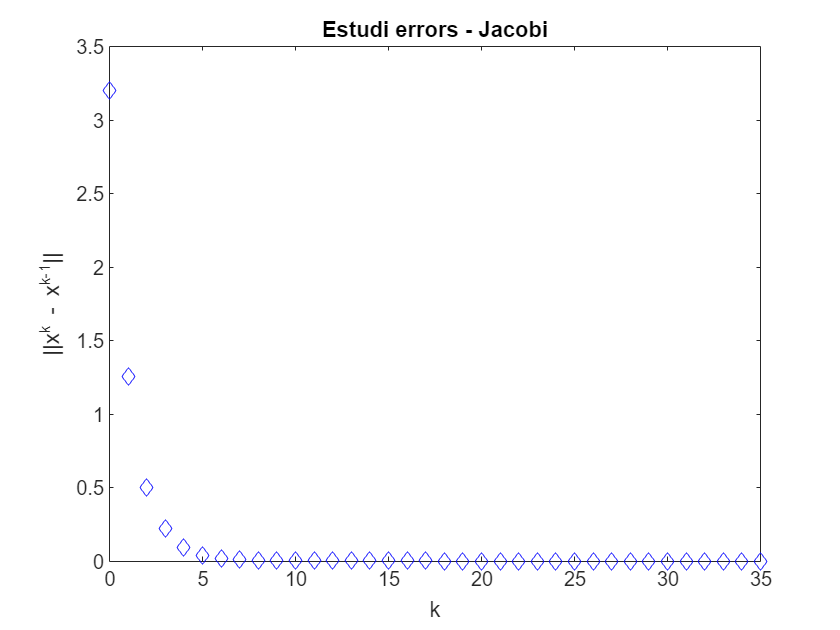

% Per fer ... resultats -> exercici5_prac03.html
clearvars
A = [15 -5 0 -5; -5 12 -2 0; 0 -2 6 -2; -5 0 -2 9];

b = [-3.45;9.96;0;0]; y = [0.14;0.95;0.37;0.16]; 

## Mètodes iteratius no estacionaris 

Consulteu en la documentació de MATLAB® - [Iterative Methods for Linear Systems](https://es.mathworks.com/help/matlab/math/iterative-methods-for-linear-systems.html)

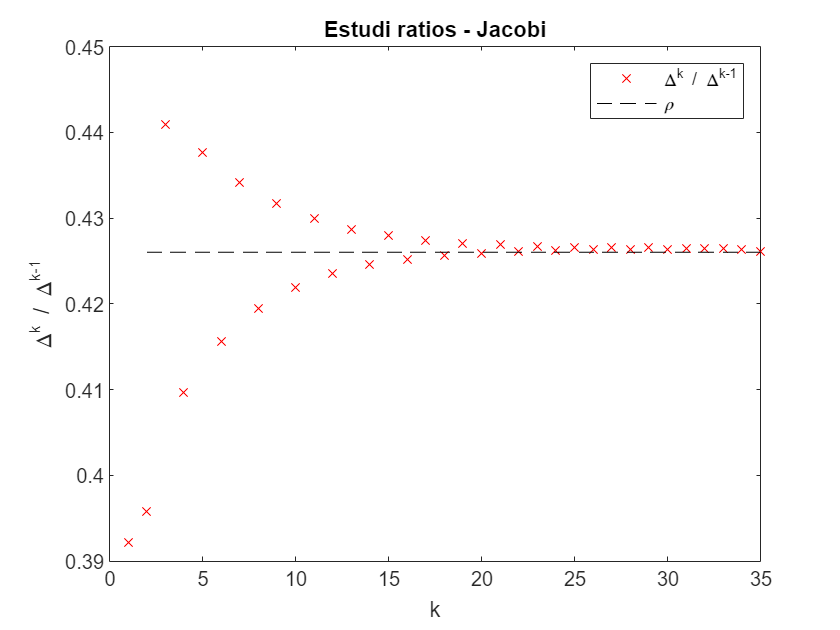

`Document preparat per M. Àngela Grau Gotés, 8 de març de 2023`